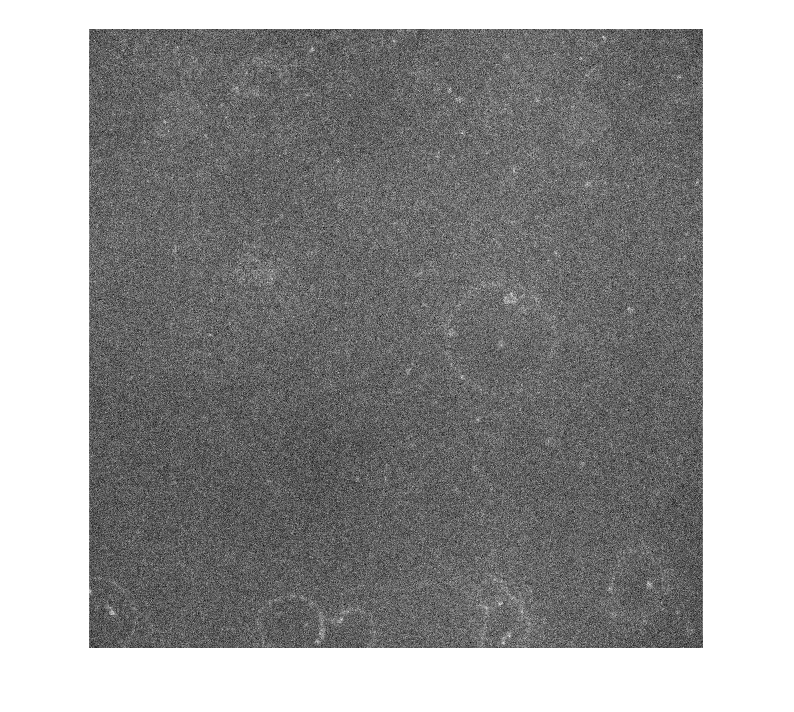

I = imread("Data/oblong_gel_ddw_sub.tif",107);
imshow(I,[])

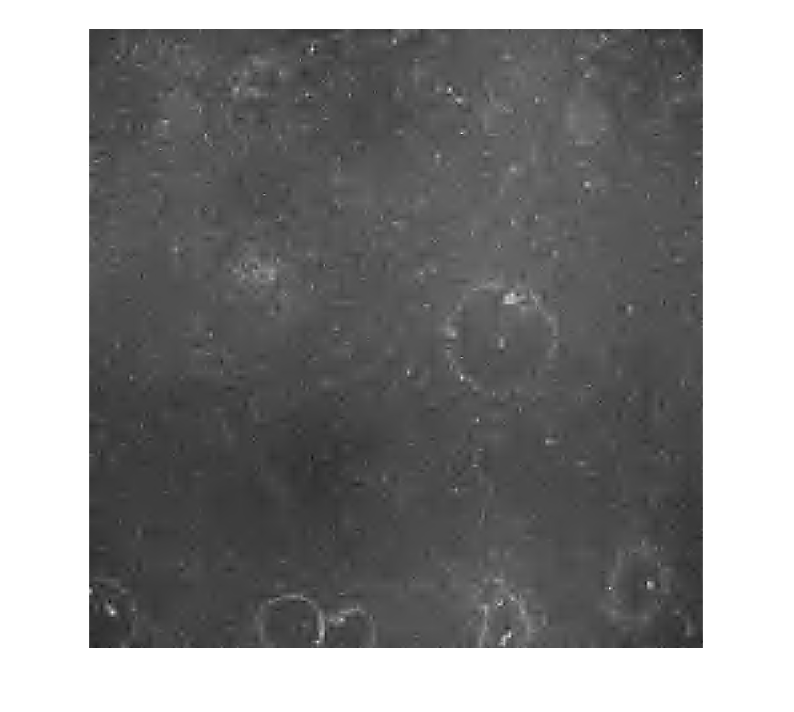

de = wdenoise2(I,'Wavelet','coif1');
imshow(de,[])

dnn = denoisingNetwork("dncnn")

dnn =   SeriesNetwork with properties:

         Layers: [59×1 nnet.cnn.layer.Layer]
     InputNames: {'InputLayer'}
    OutputNames: {'FinalRegressionLayer'}


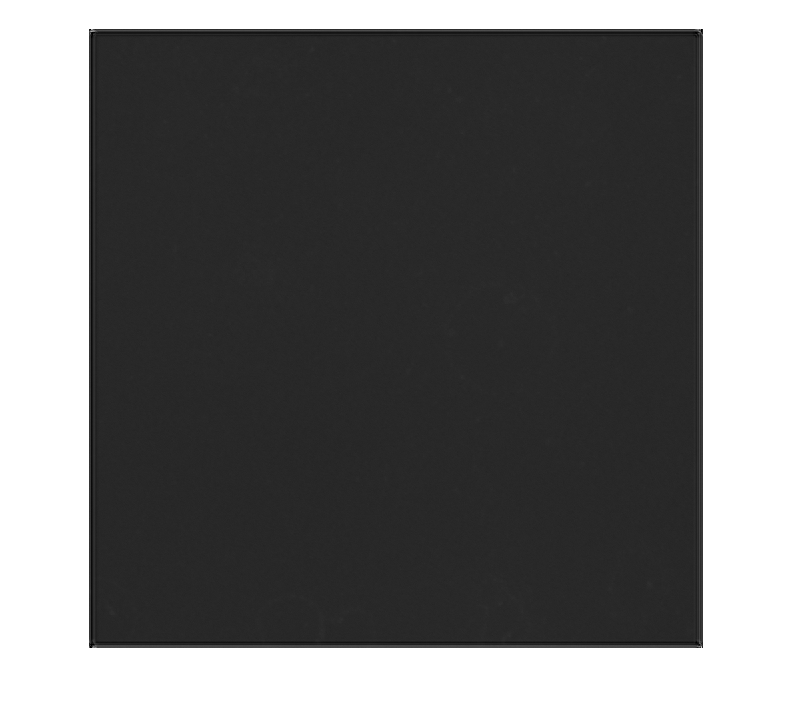

de = denoiseImage(I,dnn);
imshow(de,[])

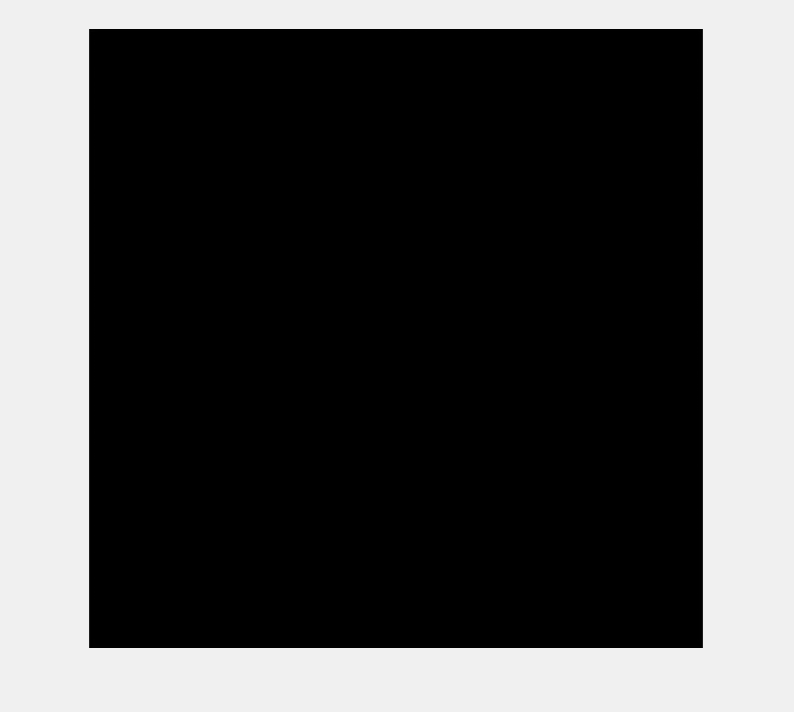

[J,rect] = imcrop(de);

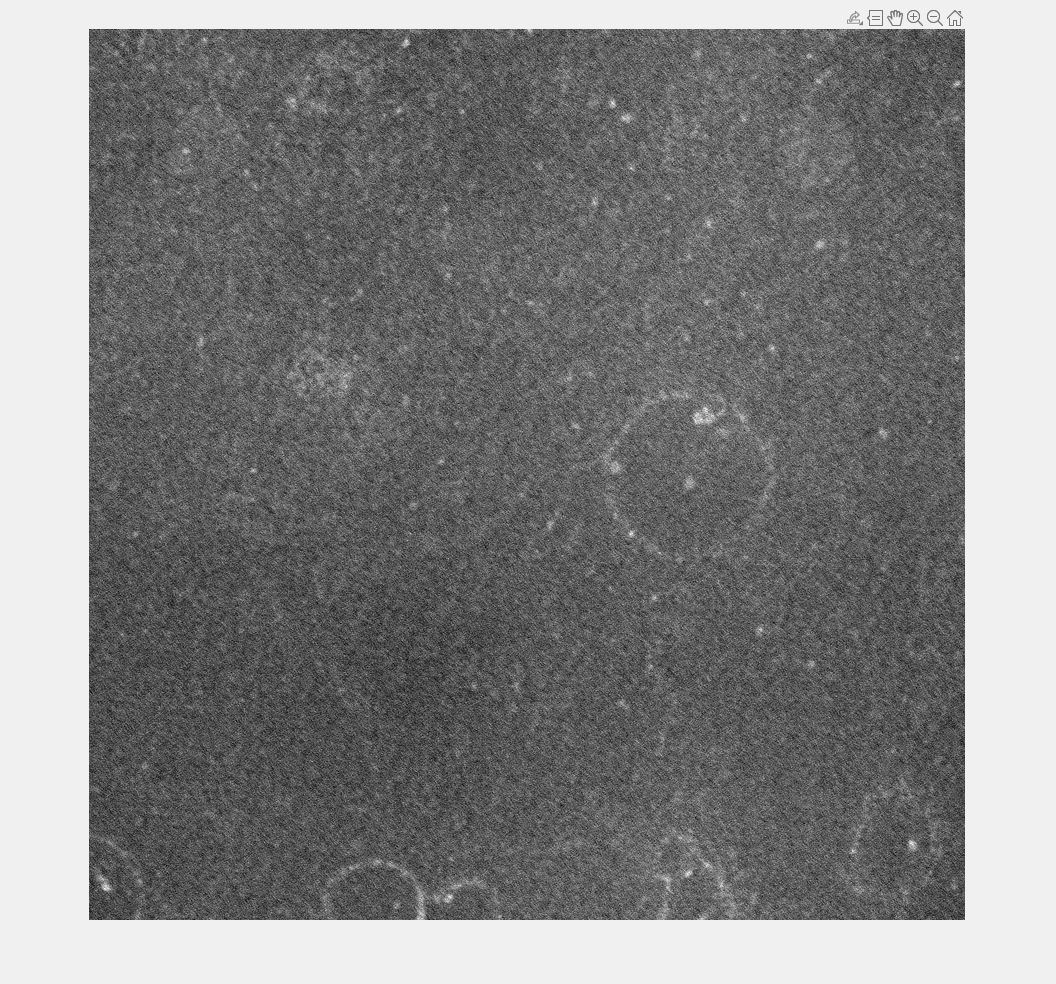

imshow(J,[])